# Problem 2

interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
R_E = 6378.1363;
R_J = 71492.0;
R_P = 1162.0;
mu_E = 398600.4415;
mu_J = 126712767.8578;
mu_P = 981.600887707;
mu_S = 132712440017.99;
a_E = 149597898.0;
a_J = 778279959.0;
a_P = 5907150229.0;
AU = 1.496e+8;

## Given

v_E_inf_mag = 12.8;
v_E_mag = sqrt(mu_S/a_E)

v_E_mag = 29.7847

v_J_mag = sqrt(mu_S/a_J)

v_J_mag = 13.0583

v_P_mag = sqrt(mu_S/a_P)

v_P_mag = 4.7399

## Part a)

Transfer Orbit Before Jupiter Encounter (Heliocentric View)

rp_T_mag = a_E + 250, r1_mag = rp_T_mag;

rp_T_mag = 149598148

vp_T_mag = v_E_inf_mag + v_E_mag

vp_T_mag = 42.5847

a_T = -mu_S * (vp_T_mag^2 - 2*mu_S/rp_T_mag)^-1

a_T = -3.3852e+09

e_T = 1 - rp_T_mag/a_T

e_T = 1.0442

Earth Parking and Hyperbolic Orbits (Geocentric View)

rp_E = R_E + 250

rp_E = 6.6281e+03

vp_E_0_mag = sqrt(mu_E/(rp_E))

vp_E_0_mag = 7.7548

vp_E_n_mag = sqrt(v_E_inf_mag^2 + 2*mu_E/rp_E)

vp_E_n_mag = 16.8557

dv1_mag = vp_E_n_mag - vp_E_0_mag

dv1_mag = 9.1009

Jupiter Encounter Before Assist (Heliocentric View)

r_2_mag = a_J

r_2_mag = 778279959

ths_2_0 = acos(1/e_T * ((a_T*(1-e_T^2)/r_2_mag)-1))

ths_2_0 = 2.1912

ths_2_0_deg = rad2deg(ths_2_0)

ths_2_0_deg = 125.5477

ths_1_0 = 0

ths_1_0 = 0

H_1_0 = conicanom(ths_1_0,e_T)

H_1_0 = 0

H_2_0 = conicanom(ths_2_0,e_T)

H_2_0 = 0.5879

TOF_E_J = timeofflight(0,ths_2_0,a_T,e_T,0,mu_S)

TOF_E_J = 3.3500e+07

TOF_E_J_day = TOF_E_J/3600/24

TOF_E_J_day = 387.7281

## Part b)

startJD = 2453754.5000000

startJD = 2.4538e+06

endJD = 2454159.5000000

endJD = 2.4542e+06

TOF_E_J_actual_day = endJD - startJD

TOF_E_J_actual_day = 405

TOF_E_J_actual_sec = TOF_E_J_actual_day * 3600 * 24

TOF_E_J_actual_sec = 34992000

## Part c)

H_2_0 = linspace(.4,.7,2^14);

for i = 1:length(H_2_0)
    TOF_test(i) = sqrt(abs(a_T)^3/mu_S) * (e_T*sinh(H_2_0(i)) - H_2_0(i));
end
diff_TOF = abs(TOF_test - TOF_E_J_actual_sec);
ind = find(min(diff_TOF) == diff_TOF)

ind = 10907

H_2_0 = H_2_0(ind), ths_2_0 = trueanom(H_2_0,e_T), ths_2_0_deg = rad2deg(ths_2_0)

H_2_0 = 0.5997

ths_2_0 = 2.2064

ths_2_0_deg = 126.4170


r_2_0_mag = a_T*(1-e_T^2)/ (1+e_T * cos(ths_2_0))

r_2_0_mag = 8.0453e+08

iCr_2_0 = [cos(ths_2_0) -sin(ths_2_0); sin(ths_2_0) cos(ths_2_0)]

iCr_2_0 =    -0.5937   -0.8047
    0.8047   -0.5937


r_2_0 = iCr_2_0 * [r_2_0_mag 0]'

r_2_0 = 	1.0e+08 *

   -4.7761
    6.4742


p_T = a_T * (1-e_T^2)

p_T = 3.0581e+08

v_2_0_mag = sqrt(mu_S*(2/r_2_0_mag - 1/a_T))

v_2_0_mag = 19.2124

gamma_2_0 = acos(sqrt(mu_S*p_T)/r_2_0_mag/v_2_0_mag)

gamma_2_0 = 1.1460

gamma_2_0_deg = rad2deg(gamma_2_0)

gamma_2_0_deg = 65.6600

v_2_0_R = v_2_0_mag * [sin(gamma_2_0); cos(gamma_2_0)]

v_2_0_R =    17.5047
    7.9184


v_2_0 = iCr_2_0 * v_2_0_R

v_2_0 =   -16.7639
    9.3855



v_J_mag = sqrt((mu_S + mu_J)/r_2_0_mag)

v_J_mag = 12.8497

v_J = iCr_2_0 * [0; v_J_mag]

v_J =   -10.3404
   -7.6283



v_inf_J_0 = v_2_0 - v_J

v_inf_J_0 =    -6.4235
   17.0139


v_inf_J_0_mag = norm(v_inf_J_0)

v_inf_J_0_mag = 18.1861

v_inf_J_0_R = iCr_2_0.' * v_inf_J_0

v_inf_J_0_R =    17.5047
   -4.9313


## Part d)

#### i)

rp_J = 200*R_J

rp_J = 14298400

a_hyp_J = -mu_J/v_inf_J_0_mag^2

a_hyp_J = -3.8313e+05

e_hyp_J = 1 - rp_J/a_hyp_J

e_hyp_J = 38.3203

delta = 2*(asin(1/e_hyp_J)),delta_deg = rad2deg(delta)

delta = 0.0522

delta_deg = 2.9907

ths_inf = acos(-1/e_hyp_J), ths_inf_deg = rad2deg(ths_inf)

ths_inf = 1.5969

ths_inf_deg = 91.4954


eta = asin(v_2_0_mag/v_inf_J_0_mag * sin(gamma_2_0)),eta_deg = rad2deg(eta)

eta = 1.2962

eta_deg = 74.2669

zeta = asin(v_J_mag/v_inf_J_0_mag * sin(gamma_2_0)),zeta_deg = rad2deg(zeta)

zeta = 0.6994

zeta_deg = 40.0731

% eta = pi - (pi-zeta) - gamma_2_0
v_inf_J_n_mag = v_inf_J_0_mag

v_inf_J_n_mag = 18.1861

v_2_n_mag = sqrt(v_J_mag^2 + v_inf_J_n_mag^2 - 2*v_J_mag*v_inf_J_n_mag*cos(eta+delta))

v_2_n_mag = 19.8182

gamma_2_n = asin(v_inf_J_n_mag/v_2_n_mag * sin(eta+delta)), gamma_2_n_deg = rad2deg(gamma_2_n)

gamma_2_n = 1.1085

gamma_2_n_deg = 63.5142


r_2_n = r_2_0

r_2_n = 	1.0e+08 *

   -4.7761
    6.4742


r_2_n_mag = norm(r_2_n)

r_2_n_mag = 8.0453e+08


v_2_n_R = v_2_n_mag * [sin(gamma_2_n); cos(gamma_2_n)]

v_2_n_R =    17.7382
    8.8384


ths_2_n = atan((r_2_n_mag * v_2_n_mag^2 / mu_S)*sin(gamma_2_n)*cos(gamma_2_n)...
    /((r_2_n_mag * v_2_n_mag^2 / mu_S)*cos(gamma_2_n)^2-1))+pi

ths_2_n = 2.0766

ths_2_n_deg = rad2deg(ths_2_n)

ths_2_n_deg = 118.9821

v_2_n = iCr_2_0 * v_2_n_R

v_2_n =   -17.6428
    9.0272



dv_eq = v_2_n - v_2_0

dv_eq =    -0.8789
   -0.3583


dv_eq_mag = norm(dv_eq)

dv_eq_mag = 0.9492

dgamma = gamma_2_n - gamma_2_0 ,dgamma_deg = rad2deg(dgamma)

dgamma = -0.0375

dgamma_deg = -2.1457

beta = asin(v_2_n_mag/dv_eq_mag * sin(dgamma)); beta = [beta pi-beta]; beta(2) = -(2*pi-beta(2))

beta =    -0.8975   -2.2441


beta_deg = rad2deg(beta)

beta_deg =   -51.4222 -128.5778



a_T_n = -mu_S * (v_2_n_mag^2 - 2*mu_S/r_2_n_mag)^-1

a_T_n = -2.1117e+09

h_2_n = cross([r_2_n;0],[v_2_n;0]), h_2_n_mag = norm(h_2_n)

h_2_n = 	1.0e+09 *

         0
         0
    7.1108


h_2_n_mag = 7.1108e+09

p_T_n = h_2_n_mag^2/mu_S

p_T_n = 3.8100e+08

e_T_n = sqrt(1-p_T_n/a_T_n)

e_T_n = 1.0865

H_2_n = conicanom(ths_2_n,e_T_n), H_2_n_deg = rad2deg(H_2_n)

H_2_n = 0.7206

H_2_n_deg = 41.2883

N_2_n = e_T_n * sinh(H_2_n) - H_2_n, N_2_n_deg = rad2deg(N_2_n)

N_2_n = 0.1319

N_2_n_deg = 7.5548

ra = a_T_n*(1+e_T_n)/a_E

ra = -29.4520

#### Plotting

plotorbit(a_E,0,0,2*pi,0) % earth
hold on
plotorbit(a_J,0,0,2*pi,0) % jupiter
plotorbit(a_P,0,0,2*pi,0) % pluto
plot(0,0,'r*','MarkerSize',2)
plotorbit(a_T,e_T,0,ths_2_0,0)
maxlim = [-a_P a_P]*1.25;
xlim(maxlim), ylim(maxlim)
dw = ths_2_n-ths_2_0;
plotorbit(a_T_n,e_T_n,ths_2_n,acos(-1/e_T_n),dw)

#### Part ii)

rp_J = 32*R_J

rp_J = 2287744

a_hyp_J = -mu_J/v_inf_J_0_mag^2

a_hyp_J = -3.8313e+05

e_hyp_J = 1 - rp_J/a_hyp_J

e_hyp_J = 6.9712

delta = 2*asin(1/e_hyp_J),delta_deg = rad2deg(delta)

delta = 0.2879

delta_deg = 16.4947

ths_inf = acos(-1/e_hyp_J), ths_inf_deg = rad2deg(ths_inf)

ths_inf = 1.7147

ths_inf_deg = 98.2473


eta = asin(v_2_0_mag/v_inf_J_0_mag * sin(gamma_2_0)),eta_deg = rad2deg(eta)

eta = 1.2962

eta_deg = 74.2669

zeta = asin(v_J_mag/v_inf_J_0_mag * sin(gamma_2_0)),zeta_deg = rad2deg(zeta)

zeta = 0.6994

zeta_deg = 40.0731

% eta = pi - (pi-zeta) - gamma_2_0
v_inf_J_n_mag = v_inf_J_0_mag

v_inf_J_n_mag = 18.1861

v_2_n_mag = sqrt(v_J_mag^2 + v_inf_J_n_mag^2 - 2*v_J_mag*v_inf_J_n_mag*cos(eta+delta))

v_2_n_mag = 22.4067

gamma_2_n = asin(v_inf_J_n_mag/v_2_n_mag * sin(eta+delta)), gamma_2_n_deg = rad2deg(gamma_2_n)

gamma_2_n = 0.9468

gamma_2_n_deg = 54.2490


r_2_n = r_2_0

r_2_n = 	1.0e+08 *

   -4.7761
    6.4742


r_2_n_mag = norm(r_2_n)

r_2_n_mag = 8.0453e+08


v_2_n_R = v_2_n_mag * [sin(gamma_2_n); cos(gamma_2_n)]

v_2_n_R =    18.1845
   13.0914


ths_2_n = atan((r_2_n_mag * v_2_n_mag^2 / mu_S)*sin(gamma_2_n)*cos(gamma_2_n)...
    /((r_2_n_mag * v_2_n_mag^2 / mu_S)*cos(gamma_2_n)^2-1))

ths_2_n = 1.5438

ths_2_n_deg = rad2deg(ths_2_n)

ths_2_n_deg = 88.4533

v_2_n = iCr_2_0 * v_2_n_R

v_2_n =   -21.3302
    6.8615



dv_eq = v_2_n - v_2_0

dv_eq =    -4.5663
   -2.5240


dv_eq_mag = norm(dv_eq)

dv_eq_mag = 5.2175

dgamma = gamma_2_n - gamma_2_0 ,dgamma_deg = rad2deg(dgamma)

dgamma = -0.1992

dgamma_deg = -11.4109

beta = asin(v_2_n_mag/dv_eq_mag * sin(dgamma)); beta = [beta pi-beta]; beta(2) = -(2*pi-beta(2))

beta =    -1.0153   -2.1263


beta_deg = rad2deg(beta)

beta_deg =   -58.1742 -121.8258



a_T_n = -mu_S * (v_2_n_mag^2 - 2*mu_S/r_2_n_mag)^-1

a_T_n = -7.7093e+08

h_2_n = cross([r_2_n;0],[v_2_n;0]), h_2_n_mag = norm(h_2_n)

h_2_n = 	1.0e+10 *

         0
         0
    1.0532


h_2_n_mag = 1.0532e+10

p_T_n = h_2_n_mag^2/mu_S

p_T_n = 8.3588e+08

e_T_n = sqrt(1-p_T_n/a_T_n)

e_T_n = 1.4437

H_2_n = conicanom(ths_2_n,e_T_n), H_2_n_deg = rad2deg(H_2_n)

H_2_n = 0.8827

H_2_n_deg = 50.5740

N_2_n = e_T_n * sinh(H_2_n) - H_2_n, N_2_n_deg = rad2deg(N_2_n)

N_2_n = 0.5637

N_2_n_deg = 32.2967

ra = a_T_n*(1+e_T_n)/a_E

ra = -12.5932

#### Plotting

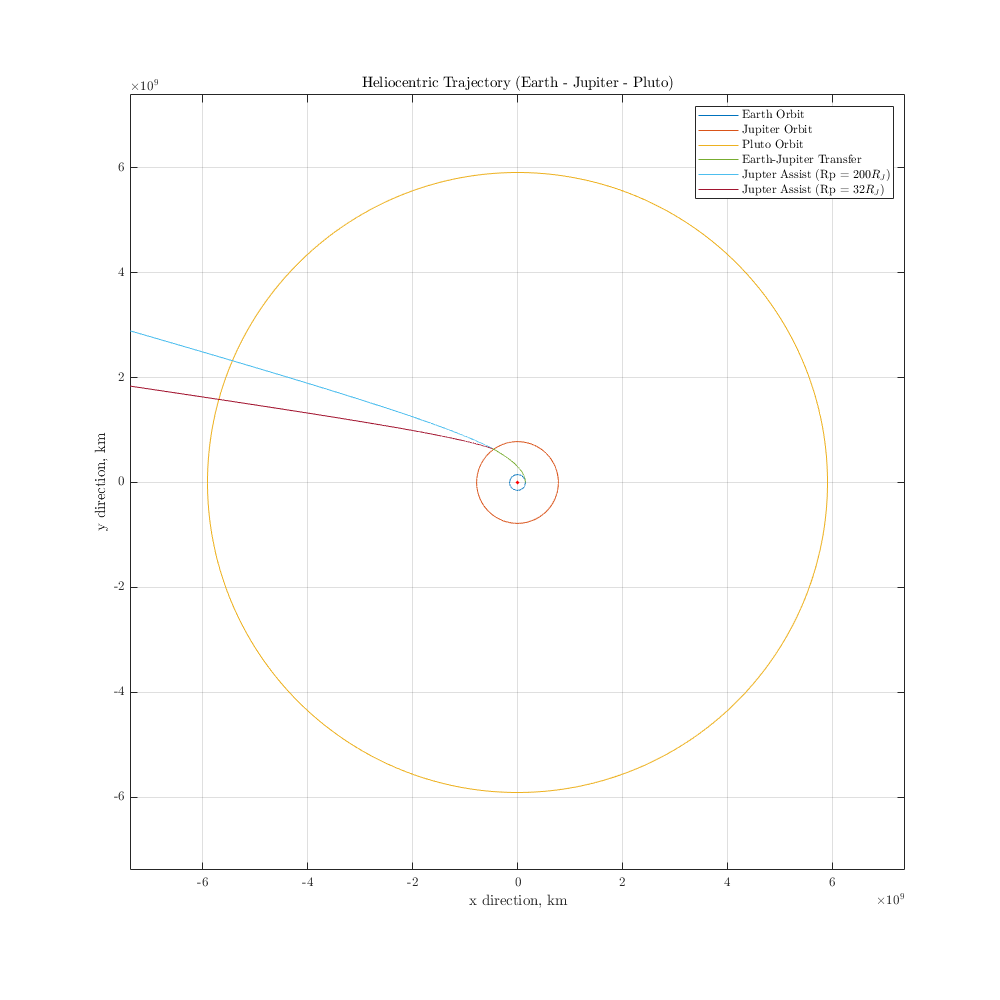

dw = ths_2_n - ths_2_0;
plotorbit(a_T_n,e_T_n,ths_2_n,acos(-1/e_T_n),dw)
maxlim = [-a_P a_P]*1.25;
xlim(maxlim), ylim(maxlim)
title('Heliocentric Trajectory (Earth - Jupiter - Pluto)')
xlabel('x direction, km')
ylabel('y direction, km')
legend('Earth Orbit','Jupiter Orbit','Pluto Orbit','','Earth-Jupiter Transfer','Jupter Assist (Rp = 200$R_{J}$)','Jupter Assist (Rp = 32$R_{J}$)')
hold off
set(gcf,'position',[0,0,1000,1000])

### Function 1: Plotting Orbit

function plotorbit(ai,ei,ths1,ths2,rotate)
ths_plot = linspace(ths1,ths2,2^12)';
ri = (ai*(1-ei^2))./(1+ei*cos(ths_plot));
ri = ri .* [cos(ths_plot-rotate),sin(ths_plot-rotate)];
plot(ri(:,1),ri(:,2))
grid on
axis equal
end